# **Results **

In this live script we will visualize the results concatenated in the .csv file named model_performance. We will strat with loading the data.

% Load data from csv
data = readtable('model_performance.csv')

data = 60×7 table
       Model        RMSE      PSNR      MAE      Dataset     NoiseType    SNRNoiseLevel
    ___________    ______    ______    ______    ________    _________    _____________

    {'Wavelet'}     0.288    10.812    0.2404    {'ARDB'}    {'COMP'}           3      
    {'LMS'    }    0.2201    13.149     0.156    {'ARDB'}    {'COMP'}           3      
    {'SR3_1'  }    0.1164    18.683    0.0728    {'ARDB'}    {'COMP'}           3      
    {'Wavelet'}     0.113    18.942    0.0811    {'ARDB'}    {'COMP'}           5      
    {'LMS'    }    0.2002     13.97     0.156    {'ARDB'}    {'COMP'}           5      
    {'SR3_1'  }    0.1113    19.073    0.0712    {'ARDB'}    {'COMP'}           5      
    {'Wavelet'}     0.288    10.812    

**ARDB - Electrode Motion - All Models - SNR 1,3,5 - MAE**

In order to avoid over plotting, we decided to use the MAE metric. (motivation: [https://hmatalonga.com/blog/choosing-between-mae-mse-and-rmse/)](https://hmatalonga.com/blog/choosing-between-mae-mse-and-rmse/)) 

According to the following paper, an appropriate technique to remove electrode motion noise is adaptive filtering:

- [https://ieeexplore.ieee.org/document/10025094](https://ieeexplore.ieee.org/document/10025094)

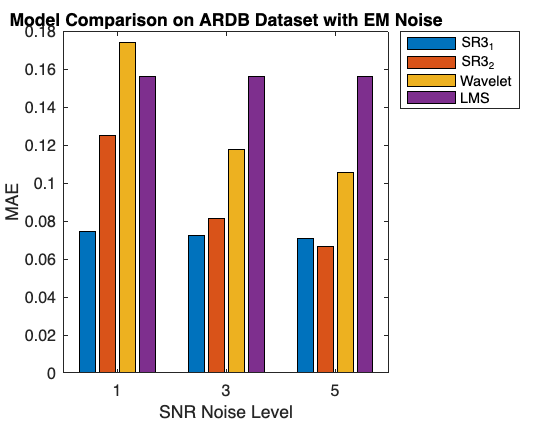

% Filter data for the specified models and conditions
filtered_data = data(strcmp(data.Model, 'SR3_1') | strcmp(data.Model, 'SR3_2') | strcmp(data.Model, 'Wavelet') | strcmp(data.Model, 'LMS'), :);
filtered_data = filtered_data(strcmp(filtered_data.Dataset, 'ARDB') & strcmp(filtered_data.NoiseType, 'EM'), :);

% Prepare data for visualization
models = {'SR3_1', 'SR3_2', 'Wavelet'};
snr_values = unique(filtered_data.SNRNoiseLevel);

figure;

metric_values = zeros(numel(snr_values), numel(models));

for i = 1:numel(models)
    for j = 1:numel(snr_values)
        model_data = filtered_data(strcmp(filtered_data.Model, models{i}) & filtered_data.SNRNoiseLevel == snr_values(j), :);
        metric_values(j, i) = mean(model_data.MAE);
    end
end

bar(metric_values);
xlabel('SNR Noise Level');
ylabel('MAE');
xticks(1:numel(snr_values));
xticklabels(arrayfun(@num2str, snr_values, 'UniformOutput', false));
legend(models, 'Location', 'bestoutside');
title('Model Comparison on ARDB Dataset with EM Noise');

Next, we will investigate the performance of all models on the MA noise.

**ARDB - Musle Artifact - All Models - SNR 1,3,5 - MAE**

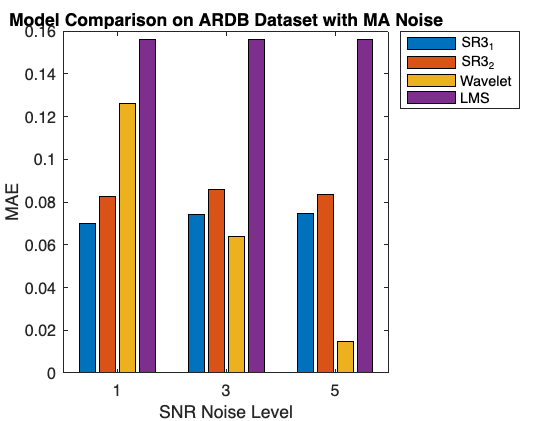

% Filter data for the specified models and conditions
filtered_data = data(strcmp(data.Model, 'SR3_1') | strcmp(data.Model, 'SR3_2') | strcmp(data.Model, 'Wavelet') | strcmp(data.Model, 'LMS'), :);
filtered_data = filtered_data(strcmp(filtered_data.Dataset, 'ARDB') & strcmp(filtered_data.NoiseType, 'MA'), :);

% Prepare data for visualization
models = {'SR3_1', 'SR3_2', 'Wavelet', 'LMS'};
snr_values = unique(filtered_data.SNRNoiseLevel);

figure;

metric_values = zeros(numel(snr_values), numel(models));

for i = 1:numel(models)
    for j = 1:numel(snr_values)
        model_data = filtered_data(strcmp(filtered_data.Model, models{i}) & filtered_data.SNRNoiseLevel == snr_values(j), :);
        metric_values(j, i) = mean(model_data.MAE);
    end
end

bar(metric_values);
xlabel('SNR Noise Level');
ylabel('MAE');
xticks(1:numel(snr_values));
xticklabels(arrayfun(@num2str, snr_values, 'UniformOutput', false));
legend(models, 'Location', 'bestoutside');
title('Model Comparison on ARDB Dataset with MA Noise');

TODO: 

- maybe let the SNR level of 5 start at the left... It should be clear that a low SNR means noisy signal... 

- Maybe also state that lower MAE is better :)

**ARDB - Composite - All Models - SNR 3,5 - MAE**

For composite noise removal, DWT (sym6) is a prefered non-ml based approach:

- https://ietresearch.onlinelibrary.wiley.com/doi/pdfdirect/10.1049/iet-spr.2020.0104

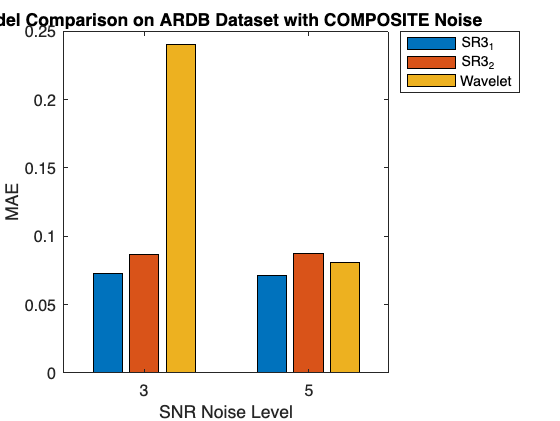

% Filter data for the specified models and conditions
filtered_data = data(strcmp(data.Model, 'SR3_1') | strcmp(data.Model, 'SR3_2') | strcmp(data.Model, 'Wavelet') | strcmp(data.Model, 'LMS'), :);
filtered_data = filtered_data(strcmp(filtered_data.Dataset, 'ARDB') & strcmp(filtered_data.NoiseType, 'COMP'), :);

% Prepare data for visualization
models = {'SR3_1', 'SR3_2', 'Wavelet', 'LMS'};
snr_values = unique(filtered_data.SNRNoiseLevel);

figure;

metric_values = zeros(numel(snr_values), numel(models));

for i = 1:numel(models)
    for j = 1:numel(snr_values)
        model_data = filtered_data(strcmp(filtered_data.Model, models{i}) & filtered_data.SNRNoiseLevel == snr_values(j), :);
        metric_values(j, i) = mean(model_data.MAE);
    end
end

bar(metric_values);
xlabel('SNR Noise Level');
ylabel('MAE');
xticks(1:numel(snr_values));
xticklabels(arrayfun(@num2str, snr_values, 'UniformOutput', false));
legend(models, 'Location', 'bestoutside');
title('Model Comparison on ARDB Dataset with COMPOSITE Noise');

Finally, we investigate the performance on the different dataset..

**AF - Composite - All Models - SNR 3,5 - MAE**

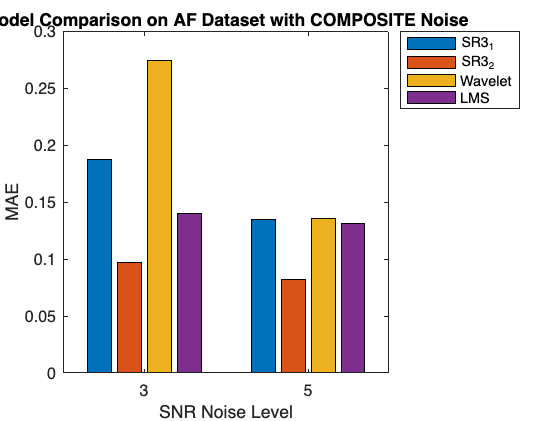

% Filter data for the specified models and conditions
filtered_data = data(strcmp(data.Model, 'SR3_1') | strcmp(data.Model, 'SR3_2') | strcmp(data.Model, 'Wavelet') | strcmp(data.Model, 'LMS'), :);
filtered_data = filtered_data(strcmp(filtered_data.Dataset, 'AF') & strcmp(filtered_data.NoiseType, 'COMP'), :);

% Prepare data for visualization
models = {'SR3_1', 'SR3_2', 'Wavelet', 'LMS'};
snr_values = unique(filtered_data.SNRNoiseLevel);

figure;

metric_values = zeros(numel(snr_values), numel(models));

for i = 1:numel(models)
    for j = 1:numel(snr_values)
        model_data = filtered_data(strcmp(filtered_data.Model, models{i}) & filtered_data.SNRNoiseLevel == snr_values(j), :);
        metric_values(j, i) = mean(model_data.RMSE);
    end
end

bar(metric_values);
xlabel('SNR Noise Level');
ylabel('MAE');
xticks(1:numel(snr_values));
xticklabels(arrayfun(@num2str, snr_values, 'UniformOutput', false));
legend(models, 'Location', 'bestoutside');
title('Model Comparison on AF Dataset with COMPOSITE Noise');